Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


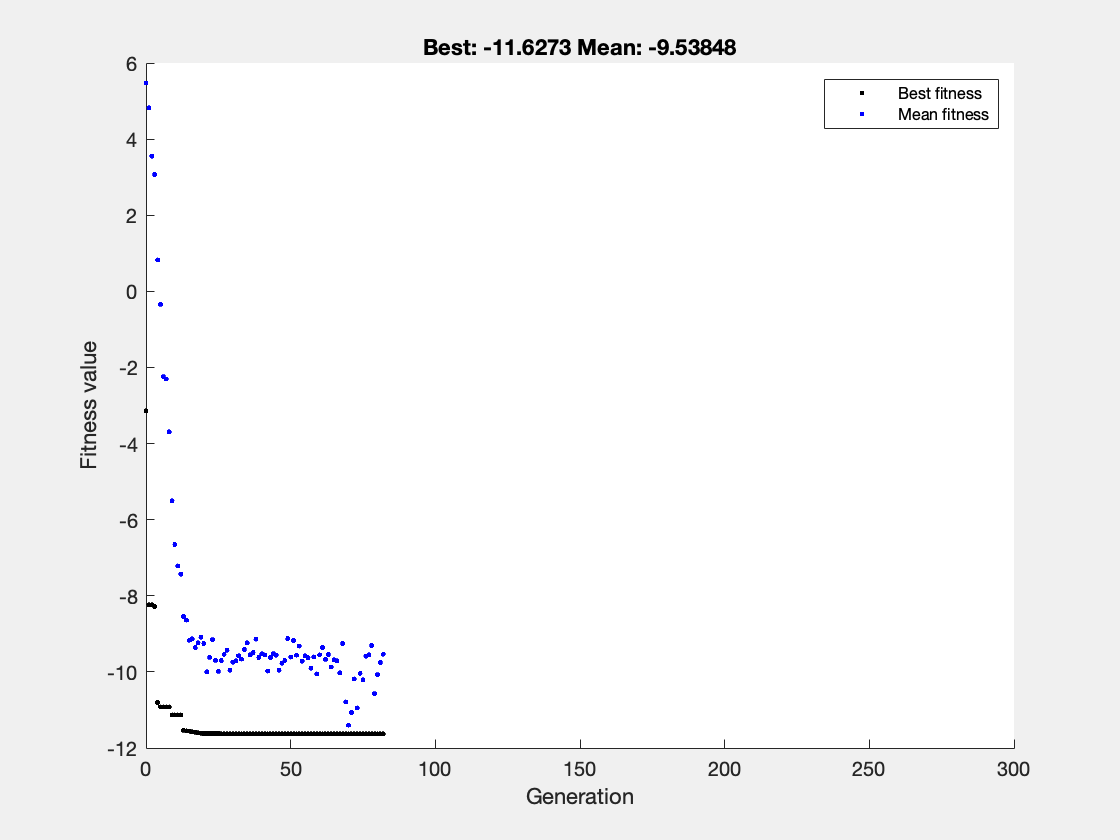

% Pass fixed parameters to objfun
objfun5 = @(x)objectiveFcn(x,a);

% Set nondefault solver options
options5 = optimoptions('ga','CrossoverFcn','crossoverheuristic','PlotFcn',...
    'gaplotbestf');

% Solve
[solution,objectiveValue] = ga(objfun5,bo,[],[],[],[],repmat(-5,bo,1),...
    repmat(5,bo,1),[],[],options5);


% Clear variables
clearvars objfun5 options5

## Results

solution

solution =    -1.1527   -1.1527   -1.1527


objectiveValue

objectiveValue = -11.6273

Error using constraintFcn
Too many output arguments.

## Modified from Matlab template by Hanfeng Zhai

*Copyright © 2020 The MathWorks, Inc.*